# Understanding the assumptions

First, we load the data

data = preprocess('data/china.csv');
[tr,y_tr,te,y_te] = train_test_split(data);
% normalise and select subfeatures
select = [true,false,true,false,true,false,true,true,true,true,false,true,false,false,true,false,false,false];
[tr,te]  = standardize(tr(:,select),te(:,select));

First, we run a simple OLS model and plot the residuals.    

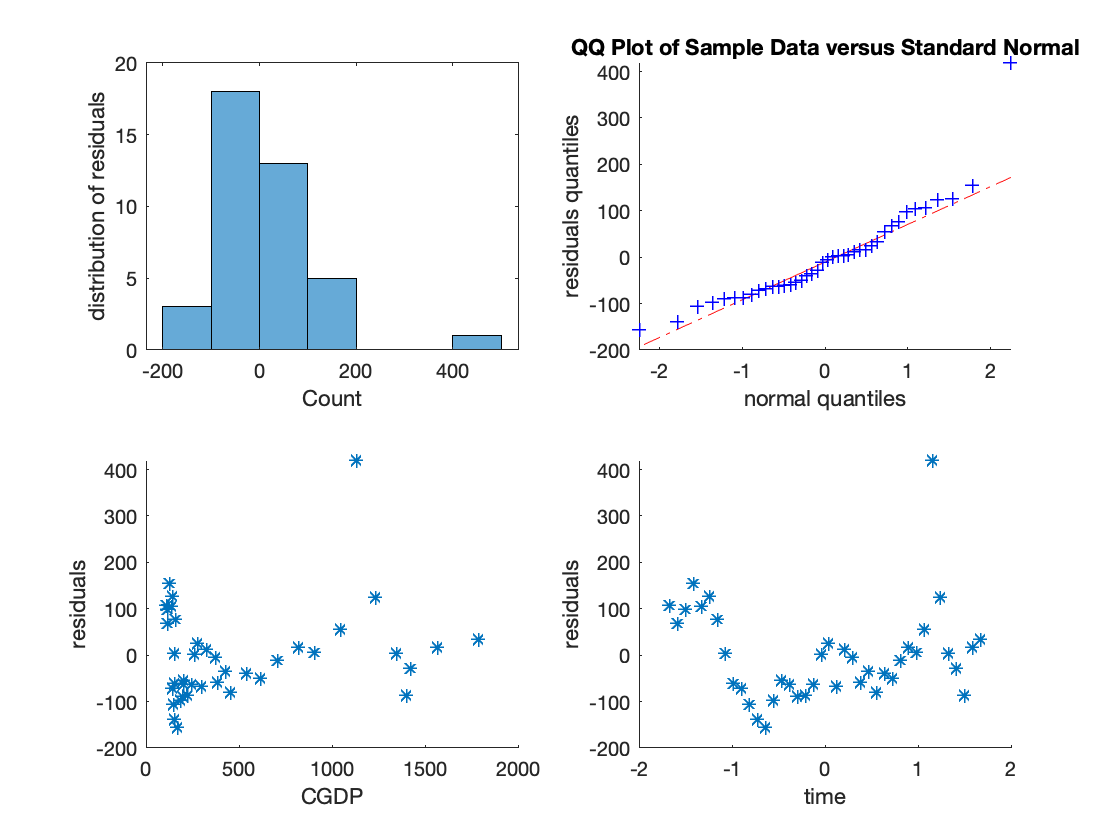

model_all = ols(tr,y_tr);
plot_residuals(model_all,tr,y_tr);

In this plot, we do not see a clear pattern but we can still observe higher variability when CGDP grows (residuals are more concentrated around 0 when CGDP is low). Therefore, we suspect the homescedasticiy assumption not to be valid. Let's test that using a Breush Pagen Test. 

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,model_all.residuals,0.95);
H

H = 1

Thefore, we reject the homescedascity assumption. The next natural step would be to look at a more general version of least square where the homoscedasticity assumption is not required to be valid. FGLS constiute the alternative we are looking for. 

It is important to deal with this issue for  the following reasons: 

1) ordinary least squares no longer produces the unbiased/constistents estimators  

2) standard errors computed using least squares can be incorrect and misleading. 

FGLS

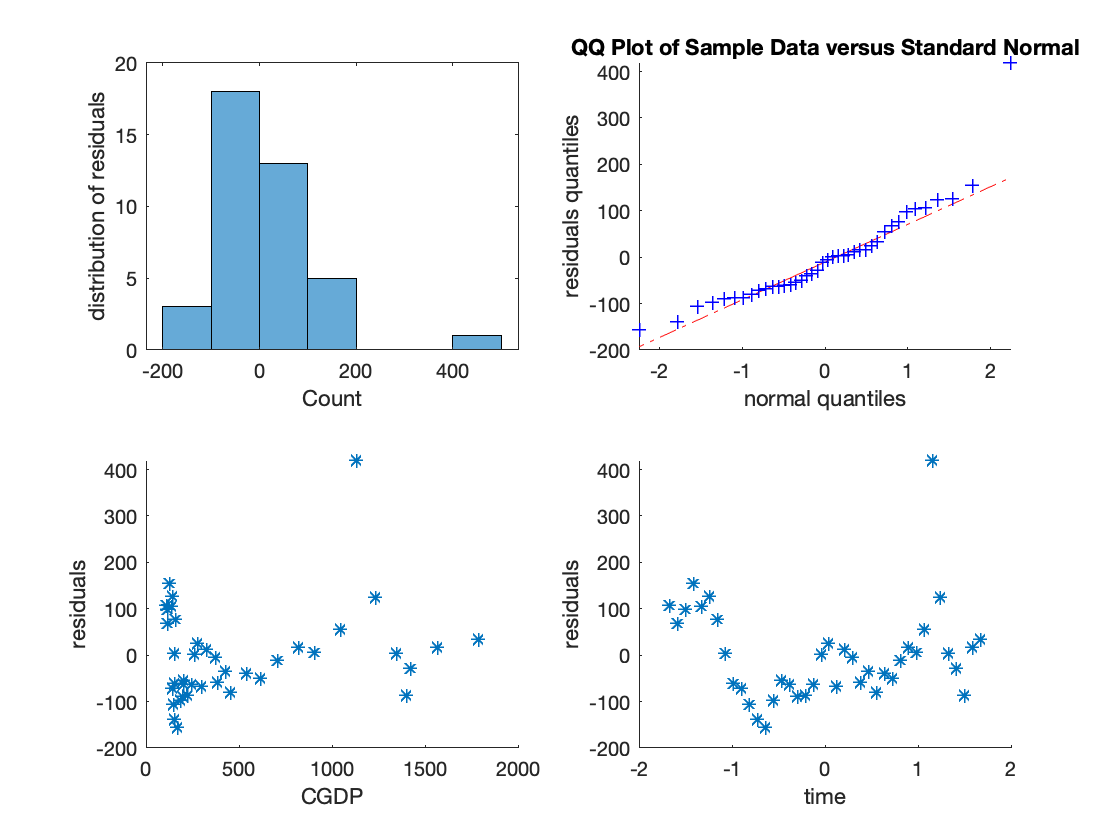

model_FGLS = FGLS(tr,y_tr);
% Breush Pagan on FGLS
[BP_stat_FGLS,BP_crit_FGLS,H_FGLS] = Breusch_Pagan_test(tr,model_FGLS.residuals,0.95);
plot_residuals(model_all,tr,y_tr);

H_FGLS

H_FGLS = 1

If we clearly see a drop in the value of the BP test, the FGLS is still not powerfull enough to caputre all the heterscedasticity assumption in our dataset.

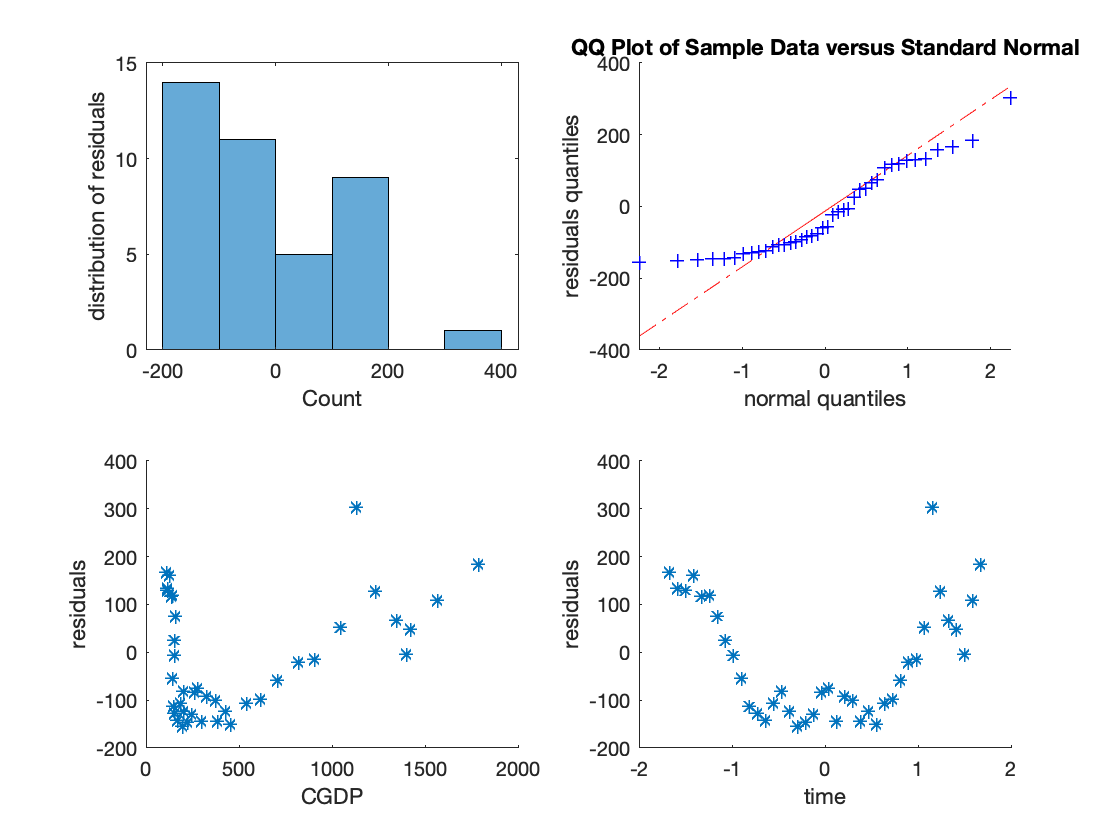

beta = fgls(tr(:,2:end),y_tr);
library_model =  compute_statistics(tr,y_tr,beta); 
[BP_stat_FGLS_2,BP_crit_FGLS_2,H_FGLS_2] = Breusch_Pagan_test(tr,library_model.residuals,0.95);
plot_residuals(library_model,tr,y_tr);

H_FGLS_2

H_FGLS_2 = 1

model_FGLS_3 = FGLS(tr,y_tr,"hetero");

A transformation was applied to X, use tX in the output


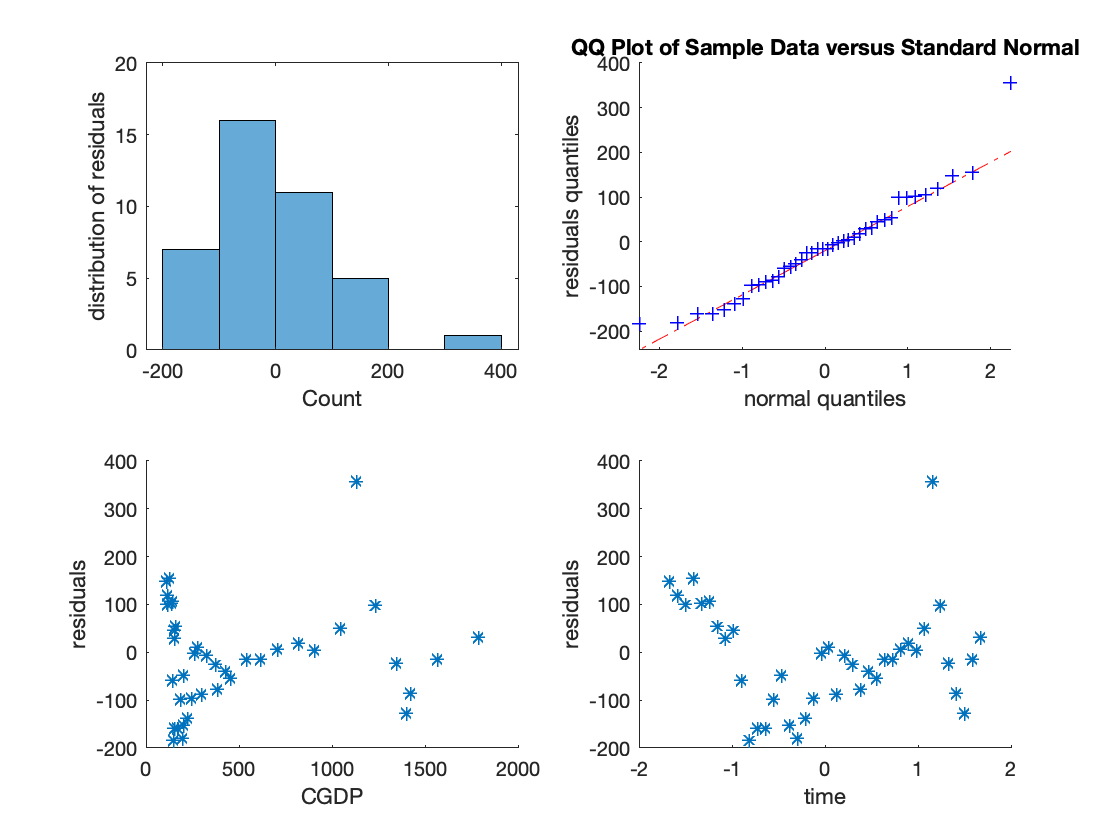

[BP_stat_FGLS_3,BP_crit_FGLS_3,H_FGLS_3] = Breusch_Pagan_test(model_FGLS_2.tX,model_FGLS_2.residuals,0.95);
plot_residuals(model_FGLS_3,tr,y_tr);

H_FGLS_3

H_FGLS_3 = 1

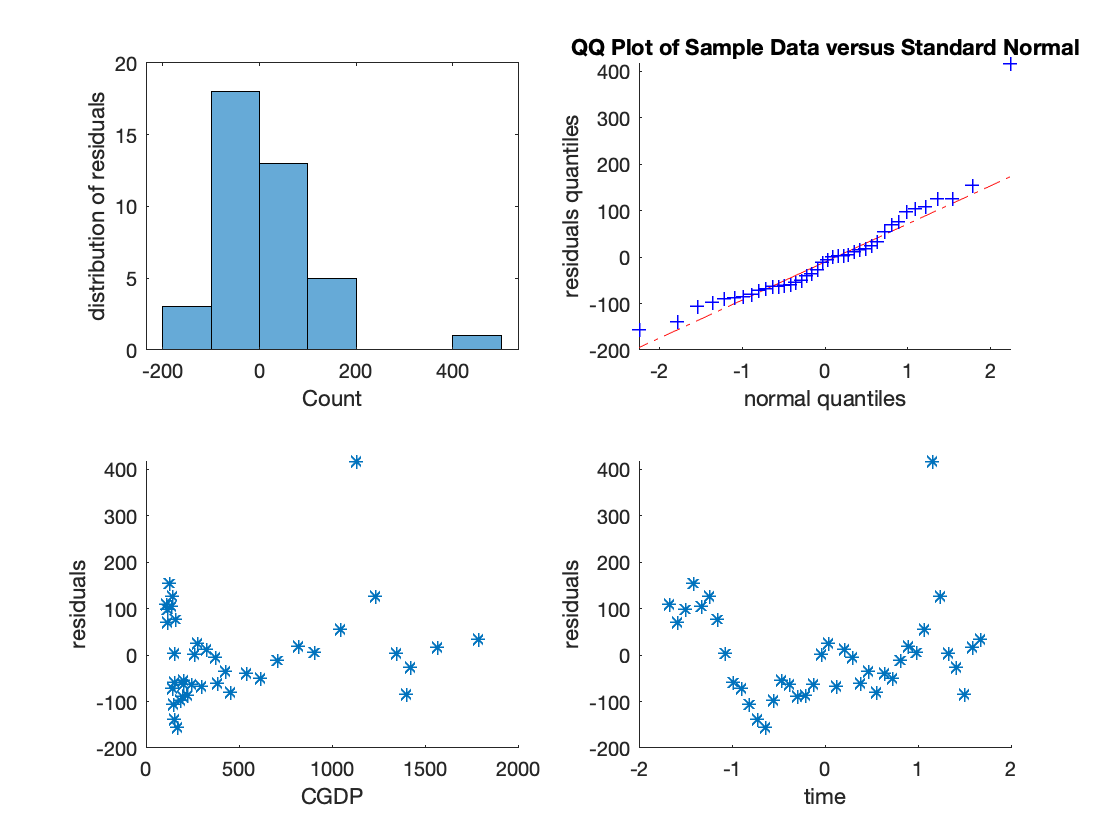

model_FGLS_4 = FGLS(tr,y_tr,"time-series");
[BP_stat_FGLS_4,BP_crit_FGLS_4,H_FGLS_4] = Breusch_Pagan_test(tr,model_FGLS_3.residuals,0.95);
plot_residuals(model_FGLS_4,tr,y_tr);

H_FGLS_4

H_FGLS_4 = 1

function [] = plot_residuals(model,X,y)
    figure;
    subplot(2,2,1);
    histogram(model.residuals);
    ylabel('distribution of residuals') ;
    xlabel('Count');
    subplot(2,2,2);
    qqplot(model.residuals);
    ylabel('residuals quantiles') ;
    xlabel('normal quantiles');
    subplot(2,2,3);
    scatter(y,model.residuals,'*');
    ylabel('residuals') ;
    xlabel('CGDP') ;
    subplot(2,2,4);
    scatter(X(:,2),model.residuals,'*');
    ylabel('residuals');
    xlabel('time') ;
end